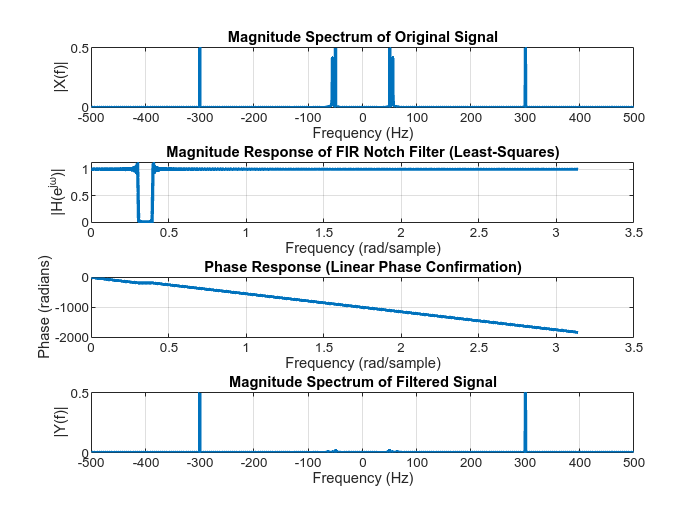

%part c:
clc; clear; close all;
fs = 1000;        
tmax = 3;            
dt = 1/fs;
t = dt:dt:tmax;   
N = length(t);

omega0 = pi/9;                
f_notch = (omega0/(2*pi))*fs;   
f_low = 50;                  
f_high = 300;                

x_low = sin(2*pi*f_low*t);
x_mid = sin(2*pi*f_notch*t);   
x_high = sin(2*pi*f_high*t);
xt = x_low + x_mid + x_high;   

Xs = fft(xt, N);
X = fftshift(Xs) / N;
freq = linspace(-fs/2, fs/2, N);

figure('Name','Least-Squares FIR Band-Stop Filter (Part c)','NumberTitle','off');
subplot(4,1,1);
plot(freq, abs(X), 'LineWidth', 2);
xlabel('Frequency (Hz)');
ylabel('|X(f)|');
title('Magnitude Spectrum of Original Signal');
grid on;

%center frequency f0=(π/9)/π = 1/9≈0.111111.
f0 = 1/9;
delta = 0.045/pi; 
f1 = f0 - delta;   %lower notch edge (normalized)
f2 = f0 + delta;   %upper notch edge 
%[0, f1] (passband), [f1, f2] (stopband), [f2, 1] (passband)
f_ls = [0, f1, f1, f2, f2, 1];
a_ls = [1, 1, 0, 0, 1, 1];  %desired amplitudes
w_ls = [1, 10, 1];
n_order = 1200; 
b = firls(n_order, f_ls, a_ls, w_ls);
y = conv(xt, b, 'same');  

[H, W] = freqz(b, 1, 4096); 
Hmag = abs(H);
Hphase = unwrap(angle(H));

subplot(4,1,2);
plot(W, Hmag, 'LineWidth', 2);
xlabel('Frequency (rad/sample)');
ylabel('|H(e^{jω})|');
title('Magnitude Response of FIR Notch Filter (Least-Squares)');
grid on;

%phase response 
subplot(4,1,3);
plot(W, Hphase, 'LineWidth', 2);
xlabel('Frequency (rad/sample)');
ylabel('Phase (radians)');
title('Phase Response (Linear Phase Confirmation)');
grid on;

Ys = fft(y, N);
Y = fftshift(Ys) / N;
subplot(4,1,4);
plot(freq, abs(Y), 'LineWidth', 2);
xlabel('Frequency (Hz)');
ylabel('|Y(f)|');
title('Magnitude Spectrum of Filtered Signal');
grid on;


omega_low = omega0 - 0.045;
omega_high = omega0 + 0.045;

[~, idx_center] = min(abs(W - omega0));
left_idx = idx_center;
while left_idx > 1 && Hmag(left_idx) < 0.707
    left_idx = left_idx - 1;
end
right_idx = idx_center;
while right_idx < length(Hmag) && Hmag(right_idx) < 0.707
    right_idx = right_idx + 1;
end
omega_left = W(left_idx);
omega_right = W(right_idx);
notch_3dB_bw = omega_right - omega_left;
fprintf('3 dB Notch Bandwidth = %.4f rad (should be <= 0.09)\n', notch_3dB_bw);

3 dB Notch Bandwidth = 0.0959 rad (should be <= 0.09)


%part d
clc; clear; close all;
A = 9;                        
wo = pi / A;                   
bw = A / 100;                 
wc1 = wo - bw/2;           
wc2 = wo + bw/2;            

%Exact L ≈ 11π/ωt + 1.
L = ceil(11*pi/0.09 + 1);
if mod(L,2)==0
    error('Filter length must be odd.');
end

M = (L - 1)/2;
display(M)

M = 192

n = 0:L-1;

fprintf('A = %d, wo = %.4f, bw = %.4f\n', A, wo, bw);

A = 9, wo = 0.3491, bw = 0.0900


fprintf('Using L = %d taps (M = %d)\n', L, M);

Using L = 385 taps (M = 192)


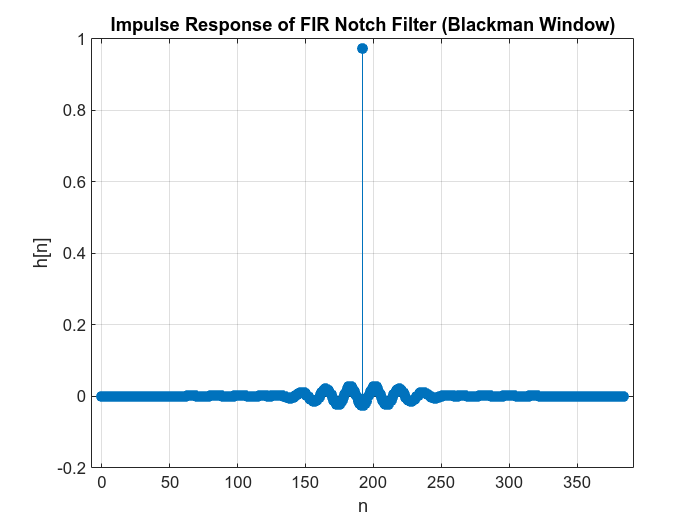


h_low1 = zeros(1, L);
h_low2 = zeros(1, L);
for k = 1:L
    if n(k) == M
        h_low1(k) = wc1 / pi;
        h_low2(k) = wc2 / pi;
    else
        h_low1(k) = sin(wc1*(n(k) - M)) / (pi * (n(k) - M));
        h_low2(k) = sin(wc2*(n(k) - M)) / (pi * (n(k) - M));
    end
end

h_bandpass = h_low2 - h_low1;
h_ap = zeros(1, L);
for k = 1:L
    if n(k) == M
        h_ap(k) = 1;
    else
        h_ap(k) = sin(pi * (n(k) - M)) / (pi * (n(k) - M));
    end
end
h_bandstop = h_ap - h_bandpass;

%blackman a = 0.42, b = 0.5, c = 0.08
w = blackman(L)';  
h_bandstop = h_bandstop .* w;

figure;
stem(n, h_bandstop, 'filled');
xlabel('n'); ylabel('h[n]');
title('Impulse Response of FIR Notch Filter (Blackman Window)');
grid on;

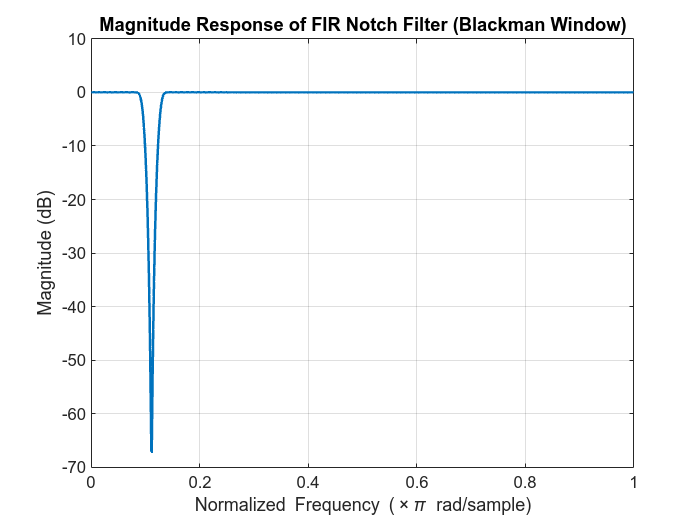


[H, w_axis] = freqz(h_bandstop, 1, 2048);
mag = abs(H);
mag_dB = 20 * log10(mag + eps);
figure;
plot(w_axis/pi, mag_dB, 'LineWidth', 1.5);
xlabel('Normalized Frequency (\times\pi rad/sample)');
ylabel('Magnitude (dB)');
title('Magnitude Response of FIR Notch Filter (Blackman Window)');
grid on;

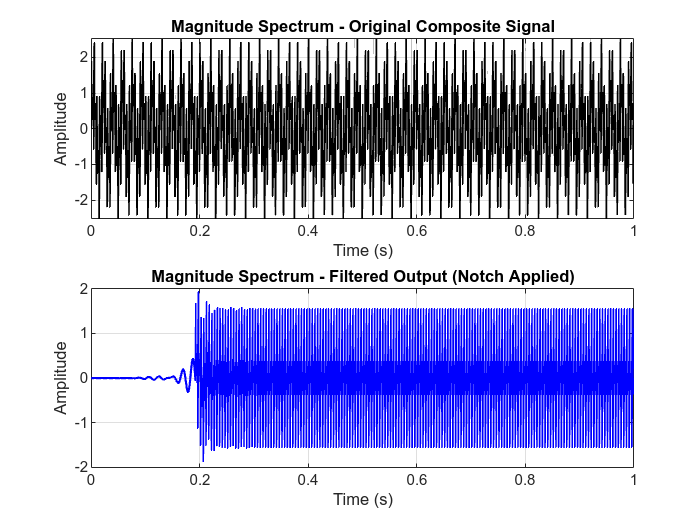


fs = 1000;                 
T = 1/fs;
t = 0:T:1-T;

f1 = fs * wo / (2*pi);
f2 = 200;                
f3 = 400;                 

x1 = sin(2*pi*f1*t);       
x2 = sin(2*pi*f2*t);      
x3 = sin(2*pi*f3*t);       
x_all = x1 + x2 + x3;

y_out = filter(h_bandstop, 1, x_all);

figure;
subplot(2,1,1);
plot(t, x_all, 'k', 'LineWidth', 1.3); grid on;
title('Magnitude Spectrum - Original Composite Signal');
xlabel('Time (s)'); ylabel('Amplitude');

subplot(2,1,2);
plot(t, y_out, 'b', 'LineWidth', 1.3); grid on;
title('Magnitude Spectrum - Filtered Output (Notch Applied)');
xlabel('Time (s)'); ylabel('Amplitude');

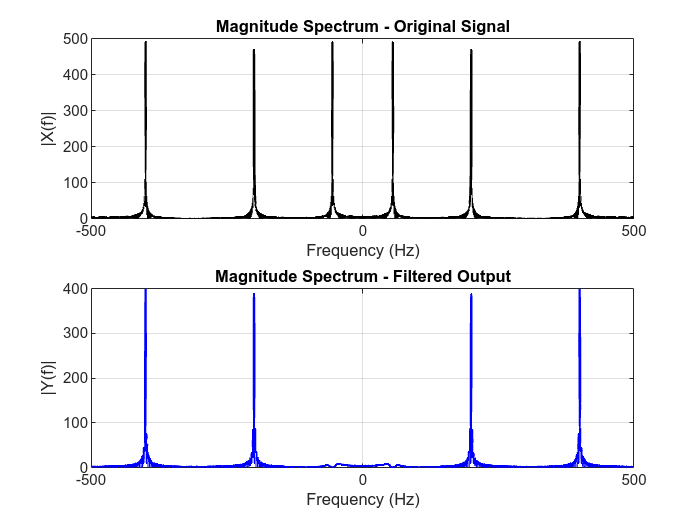


nfft = 2048;
X = fft(x_all, nfft);
Y = fft(y_out, nfft);
f_axis = linspace(-fs/2, fs/2, nfft);
figure;
subplot(2,1,1);
plot(f_axis, fftshift(abs(X)), 'k', 'LineWidth', 1.3);
title('Magnitude Spectrum - Original Signal');
xlabel('Frequency (Hz)'); ylabel('|X(f)|'); grid on;
subplot(2,1,2);
plot(f_axis, fftshift(abs(Y)), 'b', 'LineWidth', 1.3);
title('Magnitude Spectrum - Filtered Output');
xlabel('Frequency (Hz)'); ylabel('|Y(f)|'); grid on;